# KCC Kernel Derivation

This notebook will be used for the derivation of the kernel cross correlator and some of its other variations that lead into it. There is also a brief section of the training of the KCC and what takes the KCF into the KCC domain via use of objective training mapping. The final equation will then become:


$$\hat{R}_{xy} = K_t(\hat{X}, \hat{X}) \odot  \hat{H}(y)
$$


                                                                                                                                                where:


$$\hat{H}(y) = \hat{G}(z_n) \odot K_t(\hat{Y}, \hat{Y})$$


## Initial Setup

% --Setup
    clear; clc; format compact; close all; 
    % cd("/home/samkramer/Desktop/Engineering/Chirp Detection Algorithm/MAT Notebooks")

% --Declare Basic Signal

    % --Signal Parameters
        T = 1;              % Signal Period T (s)
        fs = 10000;         % Sample Rate (Hz)
        t = 0:1/fs:T;
        f = 10*2*pi;        % Frequency (Hz)

    % --Create signal
        amplitude = 0.25;
        envelope = amplitude.* sin(pi*t);
        ref_signal = envelope .* sin(f*t);

% --Creating sample signal
    t1 = 0:1/fs:5;
    amplitude = 1;
    envelope = amplitude.* sin(pi*t1);
    signal = envelope .* sin(f*t1);
    noisy_signal = randi(100,1,length(t1))./400 + signal;
    signal = noisy_signal - mean(noisy_signal);

% --Zero pad signals to make same length
    diff = length(signal) - length(ref_signal);
    pad = zeros([1, diff]);
    ref_signal_long = [ref_signal, pad];

## Derivation

### Correlation Derivation

Given that we have the following definition of the non-normalized cross correlation function xcf:


$$\hat{R}_{xy} = \hat{X} \odot \hat{Y}^*$$


Where the $^*$ denotes the complex conjugate of the vector in the fourier domain.

% --Taking fft of both signals
    xf = fft(signal);
    yf = fft(ref_signal_long);
    
% --Taking correlation
    Rxyf = xf .* conj(yf);
    Rxy = ifft(Rxyf);               % FINAL CORRELATION

We can then transform the signals by taking the kernel of both and calling this a kernel covarience function:


$$\hat{R}_{xy} = K(\hat{X}, \hat{X}) \odot K(\hat{Y}, \hat{Y})^*$$


Where $K(x,x)$ is the kernel transformation of the dataset x.

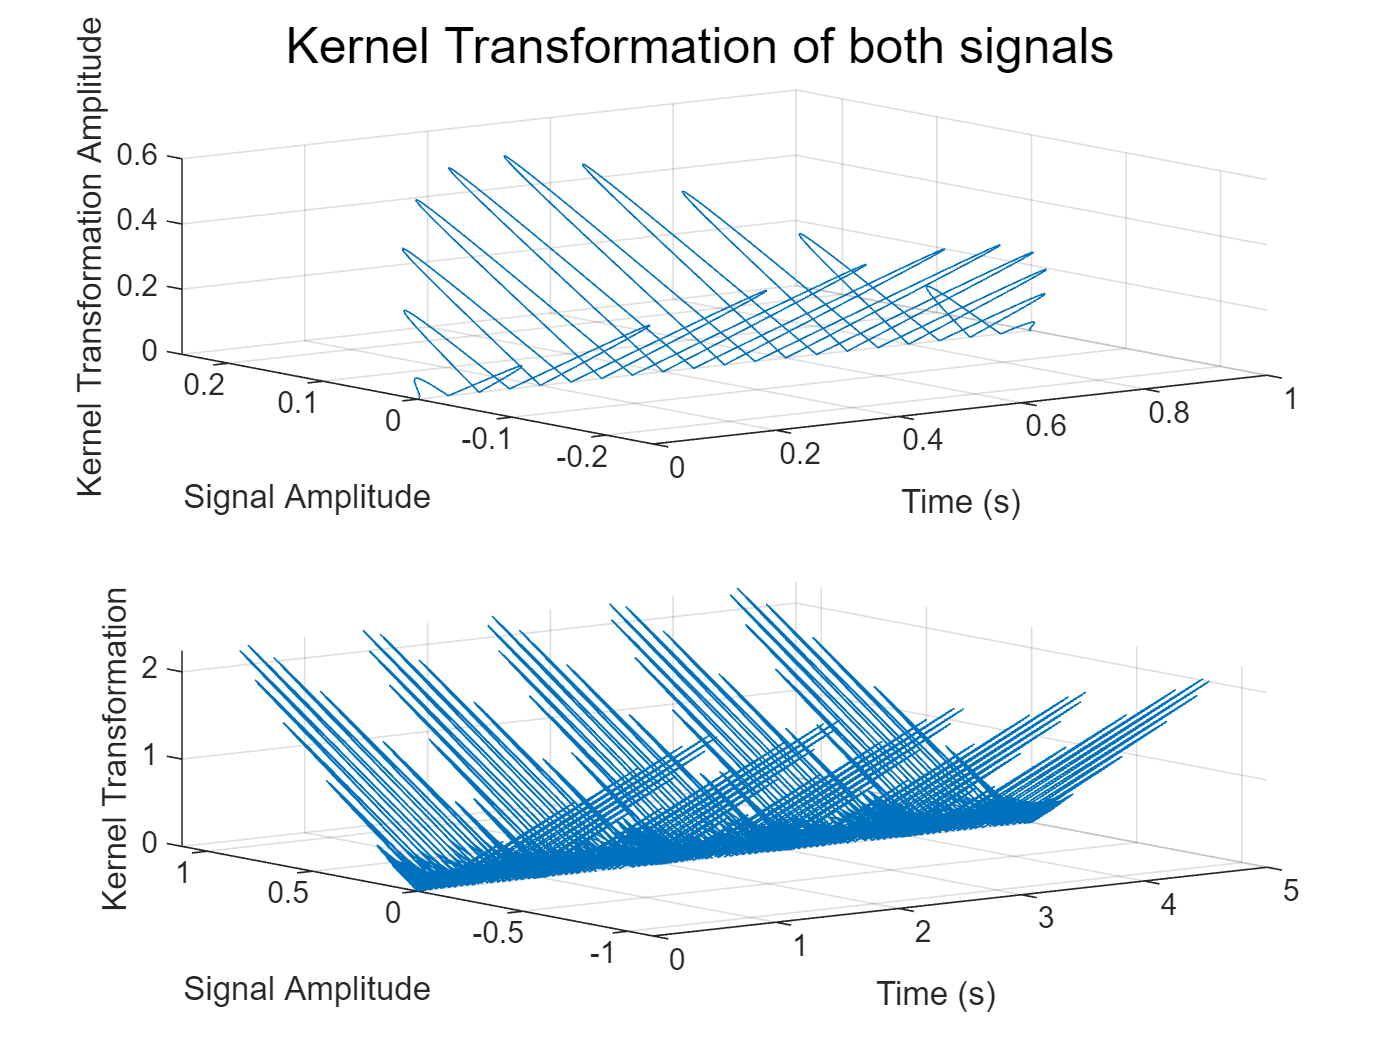

% --Taking the Kernel Kernel
    Kxx = Labs_kernel(signal, signal);                            
    Kyy = Labs_kernel(ref_signal_long, ref_signal_long);
    Kxy = Labs_kernel(signal, ref_signal_long);

% --Plot kernel functions
    figure()
    subplot(2,1,1)
    plot3(t1, ref_signal_long, Kyy)
        grid on 
        xlabel("Time (s)")
        ylabel("Signal Amplitude")
        zlabel("Kernel Transformation Amplitude")
        xlim([0 1])
    subplot(2,1,2)
    plot3(t1, signal, Kxx)
        hold on
        grid on
        xlabel("Time (s)")
        ylabel("Signal Amplitude")
        zlabel("Kernel Transformation")
        sgtitle("Kernel Transformation of both signals")

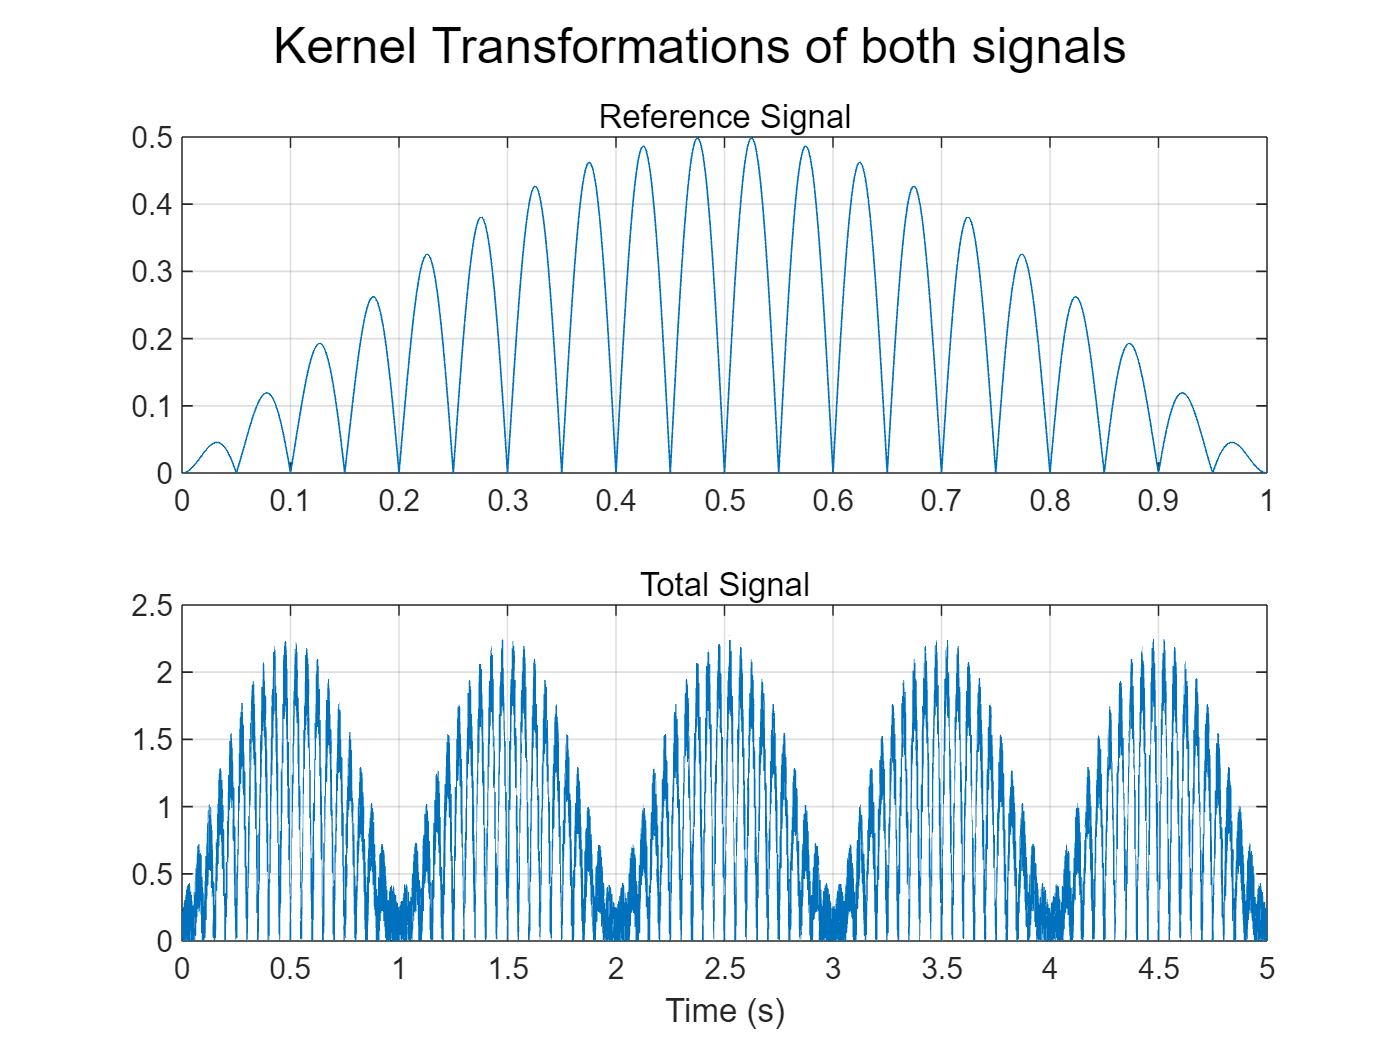

% --Plot Kernel Transformations
    figure()
    subplot(2,1,1)
    plot(t1, Kyy)
        hold on
        grid on
        subtitle("Reference Signal")
        xlim([0 1])
    subplot(2,1,2)
    plot(t1, Kxx)
        grid on
        subtitle("Total Signal")
        sgtitle("Kernel Transformations of both signals")
        xlabel("Time (s)")

Now if we were to take the correlation output of this we would essentially be doing the following mathematical equation:


$$\hat{R}_xy = |\hat{X} - \hat{X}^*| \odot |\hat{Y} - \hat{Y}^*|^*$$


is equivalent to our follwing notation:


$$\hat{R}_{xy} = K_t(\hat{X}, \hat{X}) \odot K_t(\hat{Y}, \hat{Y})$$


where the $K_t$ is our transformation kernel function $\phi(x,y)$ selected for our problem. In the above formulation we are using the L-Abs kernel. Note that this is within the frequency domain in order to speed up the process, therefore the kernel functions must be written in their frequency domain equivalents. 

To get out of the frequency domain we can then take the inverse fourier transform to get $R_{xy}$ in the temporal domain.  This yields the Kernel cross function that does not implement the training of the data needed to non-linearly describe the KCC that we are interested in exploring. KCF looks like the following:

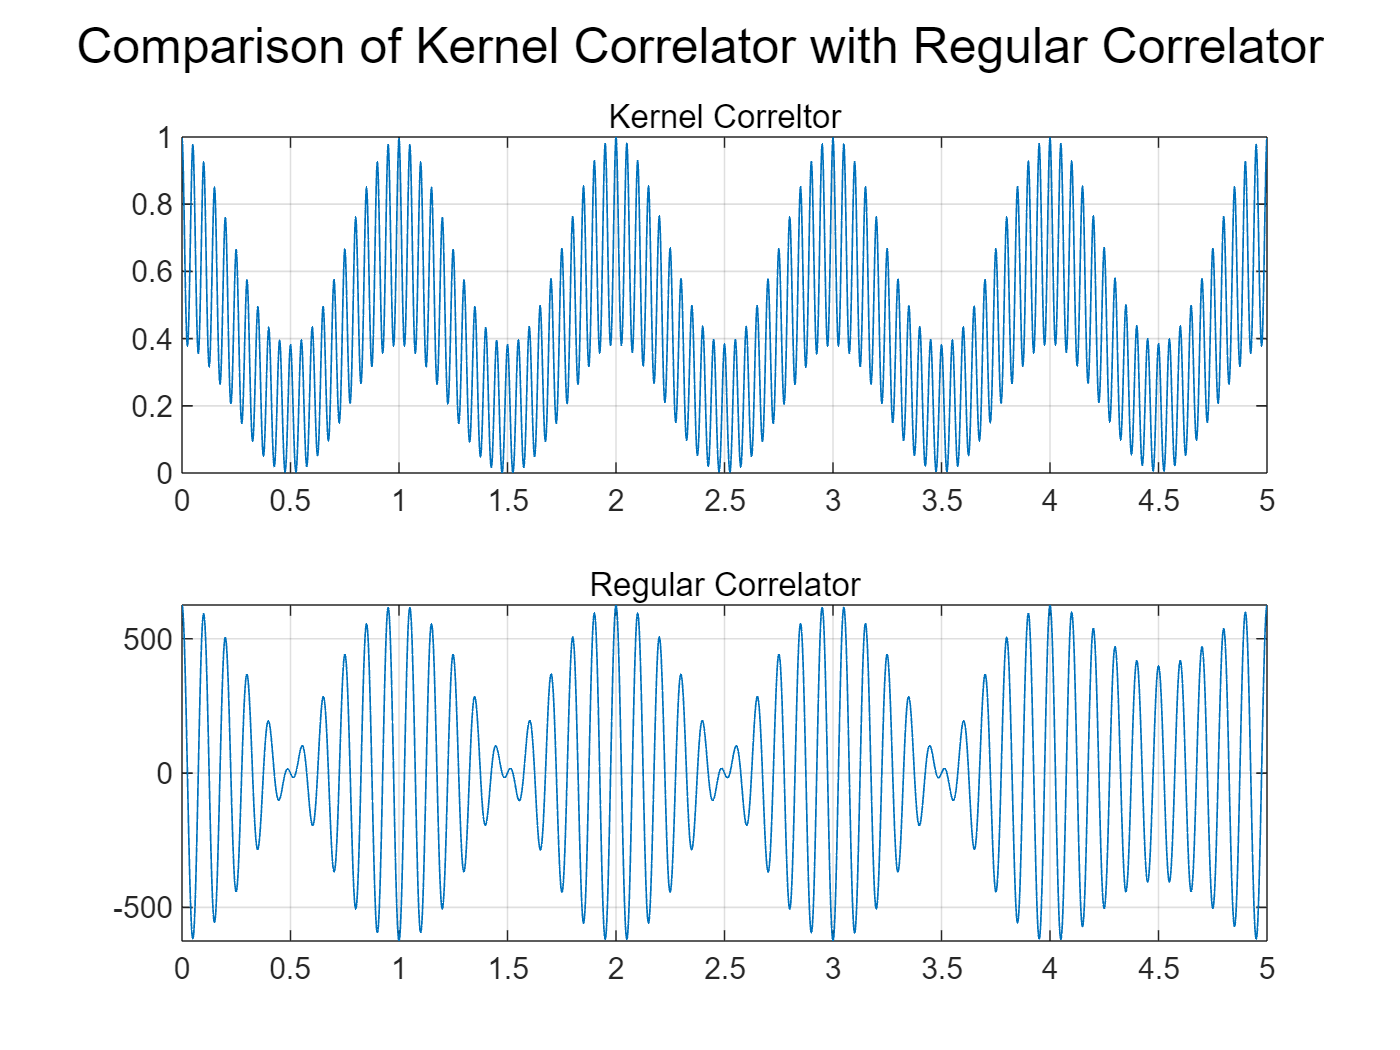

% --Finding the Correlation
    kxxf = fft(Kxx);
    kyyf = fft(Kyy);
    kxyf = fft(Kxy);
    Rxykf = kxxf.*conj(kyyf);
    Rxyk = ifft(Rxykf);
    Rxyk = Rxyk - min(Rxyk);
    Rxyk = Rxyk ./ max(Rxyk);

% --Plot
    figure()
    subplot(2,1,1)
    plot(t1, Rxyk)
        hold on
        grid on
        subtitle("Kernel Correltor")
    subplot(2,1,2)
    plot(t1, Rxy)
        hold on
        grid on
        subtitle("Regular Correlator")
        sgtitle("Comparison of Kernel Correlator with Regular Correlator")

One more key step in our formulation of the KCC is the implementation of the training mapping into our math. To do this we must redefine the reference term that we are going to be checking our signal with to be called $H(y)$ which contains our training. Right now all we have is the following:


$$\hat{H}(y) = K_t(\hat{Y}, \hat{Y})$$


Training can be seen as the convolution of the kernel transformation onto a particular training set that has been selected prior to use. In this case because we are in the frequency domain, we may multiply the sets together to train our data. $\hat{H}(y) = \hat{G}(z_n) \odot K_t(\hat{Y}, \hat{Y})$ with $n$ training vector sets $z$ within our training set $G(z)$. Those take the following: $G(z_ n) = [z_1, z_2, z_3, ... z_n]$where the number of data points in the training set must be equalivalent to the number of points in the reference signal kernel transformation, and the number of points in the data set $x$. So now our formulation becomes:


$$\hat{R}_{xy} = K_t(\hat{X}, \hat{X}) \odot  \hat{H}(y)^*
$$


                                                                                                                                                where :


$$\hat{H}(y) = \hat{G}(z_n) \odot K_t(\hat{Y}, \hat{Y})$$


The training sets must also be within the fourier domain as well. This next section will now look at three different training sets to discuss their differences and how they affect the output to the system. One will be a simple impulse trainer like before which is ones in all frequencies, the second will be the triangle trainer, and the third will be the correlation of the two signals $\hat{R}_{xy}$. The purpose is to show the differences in the training and the how they change the output data. 

If the training objective is to optimize our correlation to our training set we must minimize the error to the desired mapping of the correlation being $\hat{G}$. We can do this by finding the global minimum of the sum of squared errors for the system. The sum of squared errors for the system is chosen to ensure that the system is quadratic and has a minimum. The math is as follows:

Before training and optimization:$\hat{H}(y) =K_t(\hat{Y}, \hat{Y})$

$\frac{\hat{H}(y)} {K_t(\hat{Y}, \hat{Y})} = 1$ is our output and $\hat{G}(z_n)$ is our desired output

therefore: $\frac{\hat{H}(y)} {K_t(\hat{Y}, \hat{Y})} - \hat{G}(z_n) = e \rightarrow \sum [\frac{\hat{H}(y)} {K_t(\hat{Y}, \hat{Y})} - \hat{G}(z_n)]^2$

The optimum value of $\hat{H}(y)$ can be found at the minima of the SSE equation above


$$\frac{d}{d\hat{H}(y)}  [\frac{\hat{H}(y)} {K_t(\hat{Y}, \hat{Y})} - \hat{G}(z_n)]^2 = 0$$



$$2[\frac{\hat{H}(y)} {K_t(\hat{Y}, \hat{Y})} - \hat{G}(z_n)][\frac{1}{{K_t(\hat{Y}, \hat{Y})}}] =0$$



$$2\frac{\hat{H}(y)} {K_t^2(\hat{Y}, \hat{Y})} - 2\frac{\hat{G}(z_n)}{K_t(\hat{Y}, \hat{Y})}=0$$



$$\hat{H}(y) =2\frac{\hat{G}(z_n)}{K_t(\hat{Y}, \hat{Y})}(\frac {K_t^2(\hat{Y}, \hat{Y})}{2})$$



$$\hat{H}(y) ={\hat{G}(z_n)}{K_t(\hat{Y}, \hat{Y})}$$


Therefore, our mapping to the desired output will then be equivalent to the assumed solution above that we had

## Training Exploration

The goal of the training set is purely for prediction of the outputs for more control during automation tasks. The training can take the form of any function, but some may work better for the purpose of signal detection. Training is not necessary for the correlation process, but can manipulate our outputs for better signal detection properties. 

### Single Training Sets

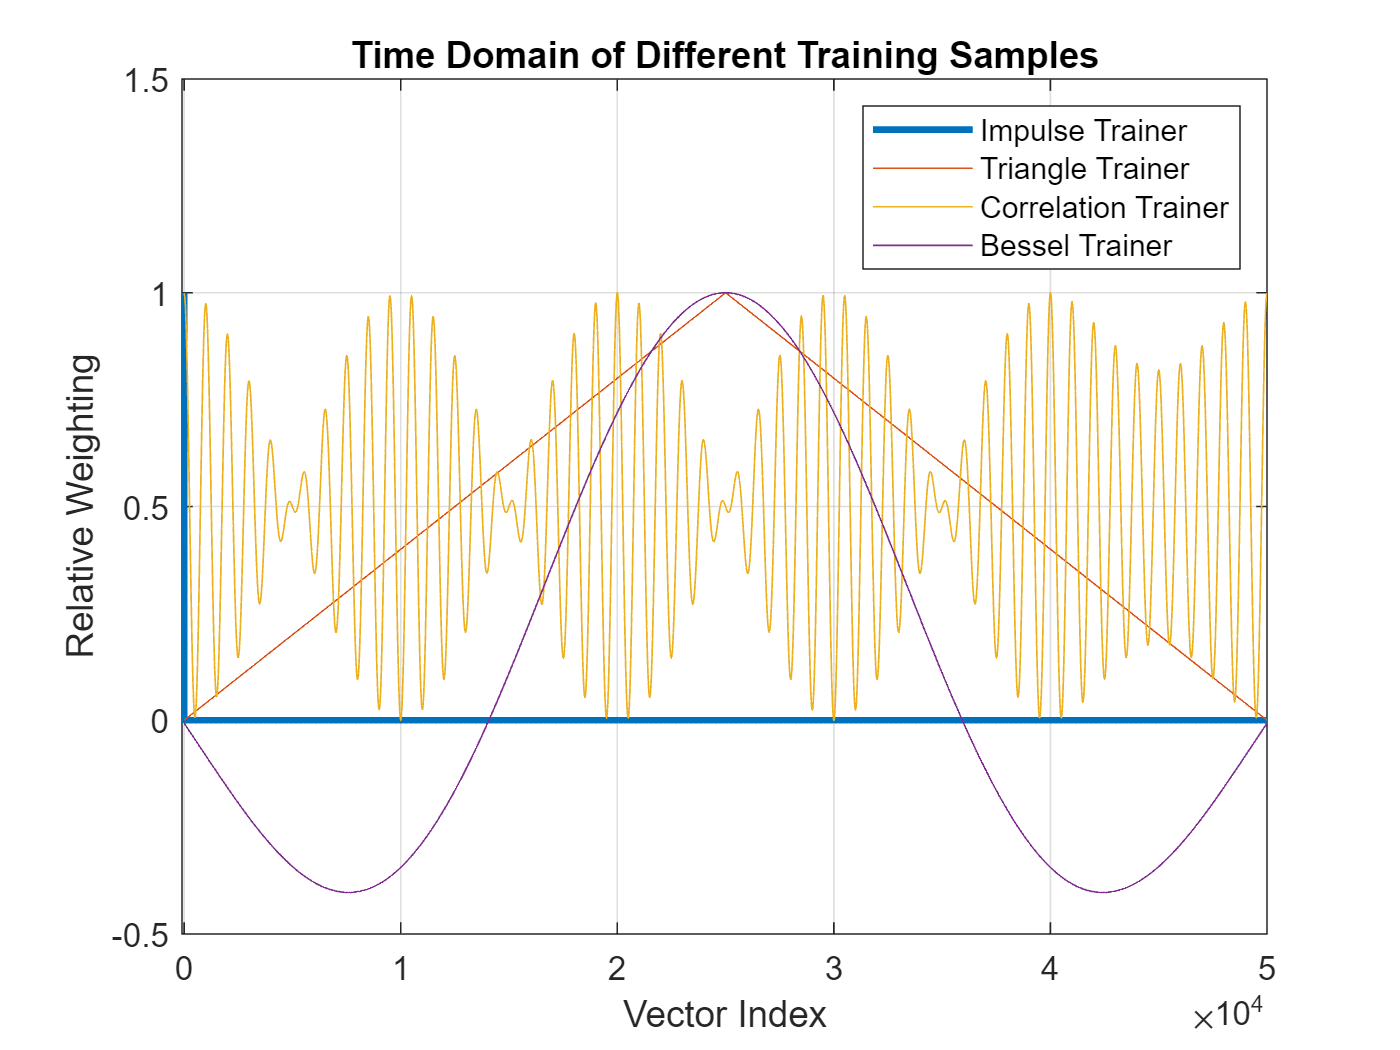

% --Define Impulse trainer
    g_hat_impulse = ones(1,length(ref_signal_long));        % This is the trainer within the fourier domain
    g_impulse = ifft(g_hat_impulse);

% --Triangle Trainer
    x = 0:length(ref_signal_long)/2;
    x = [x flip(x)];
    x = x(1:end - 1);
    g_triangle = 1/max(x) .* x;
    g_hat_tri = fft(g_triangle);

% --Correlation Trainer
    g_hat_corr = Rxyf;
    g_corr = ifft(g_hat_corr);
    g_corr = (g_corr - min(g_corr));
    g_corr = g_corr ./(max(g_corr));

% --Bessel trainer
    z = linspace(0,5.5, length(t1)./2);
    g_bessel_1 = besselj(0,z);
    z = linspace(0,5.5, (length(t1)./2) + 1);
    g_bessel_2 = besselj(0,z);
    g_bessel = [flip(g_bessel_2), g_bessel_1];
    g_hat_bessel = fft(g_bessel);

% --THEREFORE OUR TRAINERS IN THE FREQ DOMAIN:
    g_hat_corr;         % Correlation Trainer
    g_hat_tri;          % Triangle Wave Trainer
    g_hat_impulse;      % Impulse Trainer

% --Plotting
    figure()
    plot(g_impulse, "linewidth", 2)
        hold on
        grid on
    plot(g_triangle)
    plot(g_corr)
    plot(g_bessel)
    xlim([-100 50001])
    ylim([-0.5 1.5])
    legend("Impulse Trainer", "Triangle Trainer", "Correlation Trainer", "Bessel Trainer")
    title("Time Domain of Different Training Samples")
    ylabel("Relative Weighting")
    xlabel("Vector Index")

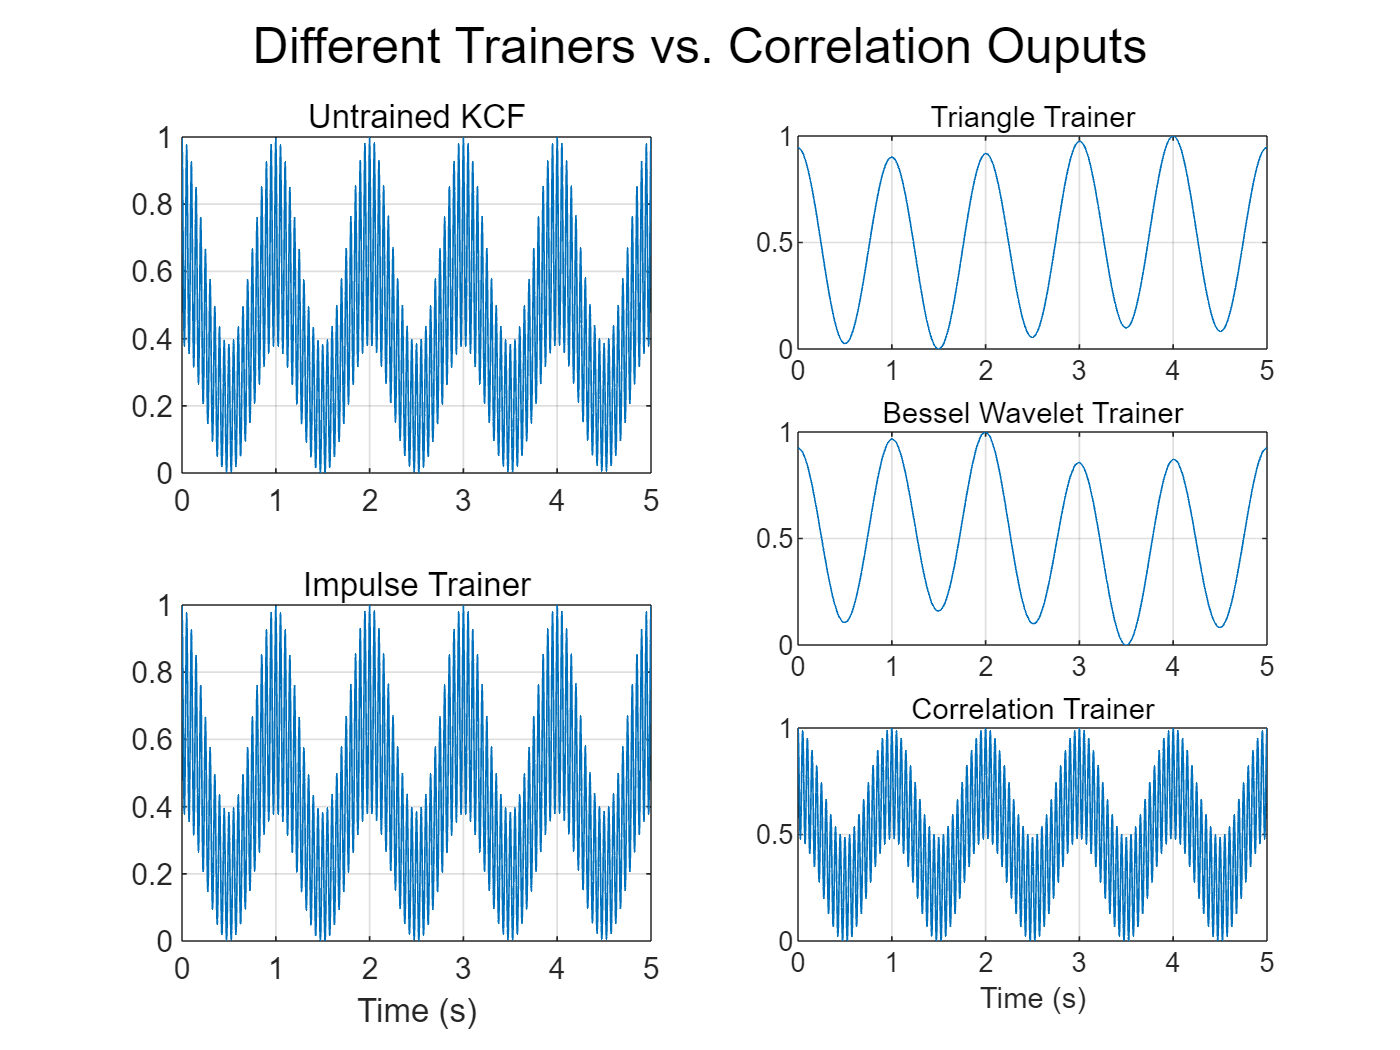

% --Exploring using the Impulse trainer
    Rxyk_impulse = ifft(kxxf .* conj(g_hat_impulse .* kyyf));
    Rxyk_impulse = Rxyk_impulse - min(Rxyk_impulse);
    Rxyk_impulse = Rxyk_impulse ./ max(Rxyk_impulse);

% --Exploring using Triangular trainer
    Rxyk_triangle = -1 .* ifft(kxxf .* conj(g_hat_tri .* kyyf));
    Rxyk_triangle = Rxyk_triangle - min(Rxyk_triangle);
    Rxyk_triangle = Rxyk_triangle ./ max(Rxyk_triangle);

% --Exploring using Bessel Trainer
    Rxyk_Bessel = ifft(kxxf .* conj((g_hat_bessel .* (kyyf ))));
    Rxyk_Bessel = Rxyk_Bessel - min(Rxyk_Bessel);
    Rxyk_Bessel = Rxyk_Bessel ./ max(Rxyk_Bessel);

% --Exploring using Correlation Trainer
    Rxyk_corr = ifft(kxxf .* conj((kxxf.*conj(kyyf)) .* kyyf));
    Rxyk_corr = Rxyk_corr - min(Rxyk_corr);
    Rxyk_corr = Rxyk_corr ./ max(Rxyk_corr);
    
% --Plotting output
    figure()
    subplot(2,2,1)
    plot(t1, Rxyk)
        hold on
        grid on
        subtitle("Untrained KCF")
        xlim([0 5])
    subplot(2,2,3)
    plot(t1, Rxyk_impulse)
        grid on
        subtitle("Impulse Trainer")
        xlabel("Time (s)")
        xlim([0 5])
    subplot(3,2,2)
    plot(t1, Rxyk_triangle)
        hold on
        grid on
        subtitle("Triangle Trainer")
        xlim([0 5])
    subplot(3,2,4)
    plot(t1, Rxyk_Bessel)
        hold on
        grid on
        subtitle("Bessel Wavelet Trainer")
        sgtitle("Different Trainers vs. Correlation Ouputs")
        xlim([0 5])
    subplot(3,2,6)
    plot(t1, Rxyk_corr)
        xlabel('Time (s)')
        hold on
        grid on
        subtitle("Correlation Trainer")

                In the above figure, we can see that the untrained and the impulse functions remain relatively the same because of the mathematics of the impulse in the frequency domain: impulses contain infinite frequencies with equivalent energy, so therefore we are putting equivalent energy into our system without favoring or biasing the output. The triangle trainer will limit the frequencies to only low frequencies, acting almost as a smoothing function to the system. The idea of the correlation trainer was to implicitly tie in the traditional correlation function into the KCC however, it did not seem to have any effect on the system when in the time domain version, and had negative effect on the output when in the frequency domain, despite the peaks appearing in the same places. This may not be the best route, but could be useful later with another application of a kernel transformation.

                As we can see from the figure, the KCC will yield similar results from an impulse trained function and a correlation trained function, which brings up the question, do the training functions need to be kernelized to achieve the proper outputs? This will be discussed in the next section below where each of the trainers will be passed through a time domain kernel and then the correlation will be found in the frequency domain. However, this may not be useful as we may be squaring our system kernelizing our correlation trainer. This may not be as effective as I think it could be. Better to stick with other ideas. 

                The Bessel function trainer which is more of a wavelet has low frequencies present in it as well so therefore it has the same sort of smoothing principles of the the triangular wavelet. It also is reflected around its center compared to the triangle trainer. 

### Multiple Kernels and Training Sets

                These can be combined together to train our system in different ways and achieve different performances. The math can be seen below:

Given that we have $m$ training sets that we want to use and a signal and reference signal with $n$ vectors we must have a training set $\hat{g}$ be size [$n$ x 1] for a time history signal

$\hat{g}_m$ = [ $\hat{g}_1$, $\hat{g}_2$, $\hat{g}_3$, ... $\hat{g}_m$]

[$n$ x $m$]

then when we find the multiplication of the following: 


$$\hat{g}_m \odot K_t(\hat{Y}, \hat{Y})$$


[$n$ x $m$] [$n$ x 1]

which means that all the signals in the training set must be element wise multipled together in order to return a mathematically correct data set.

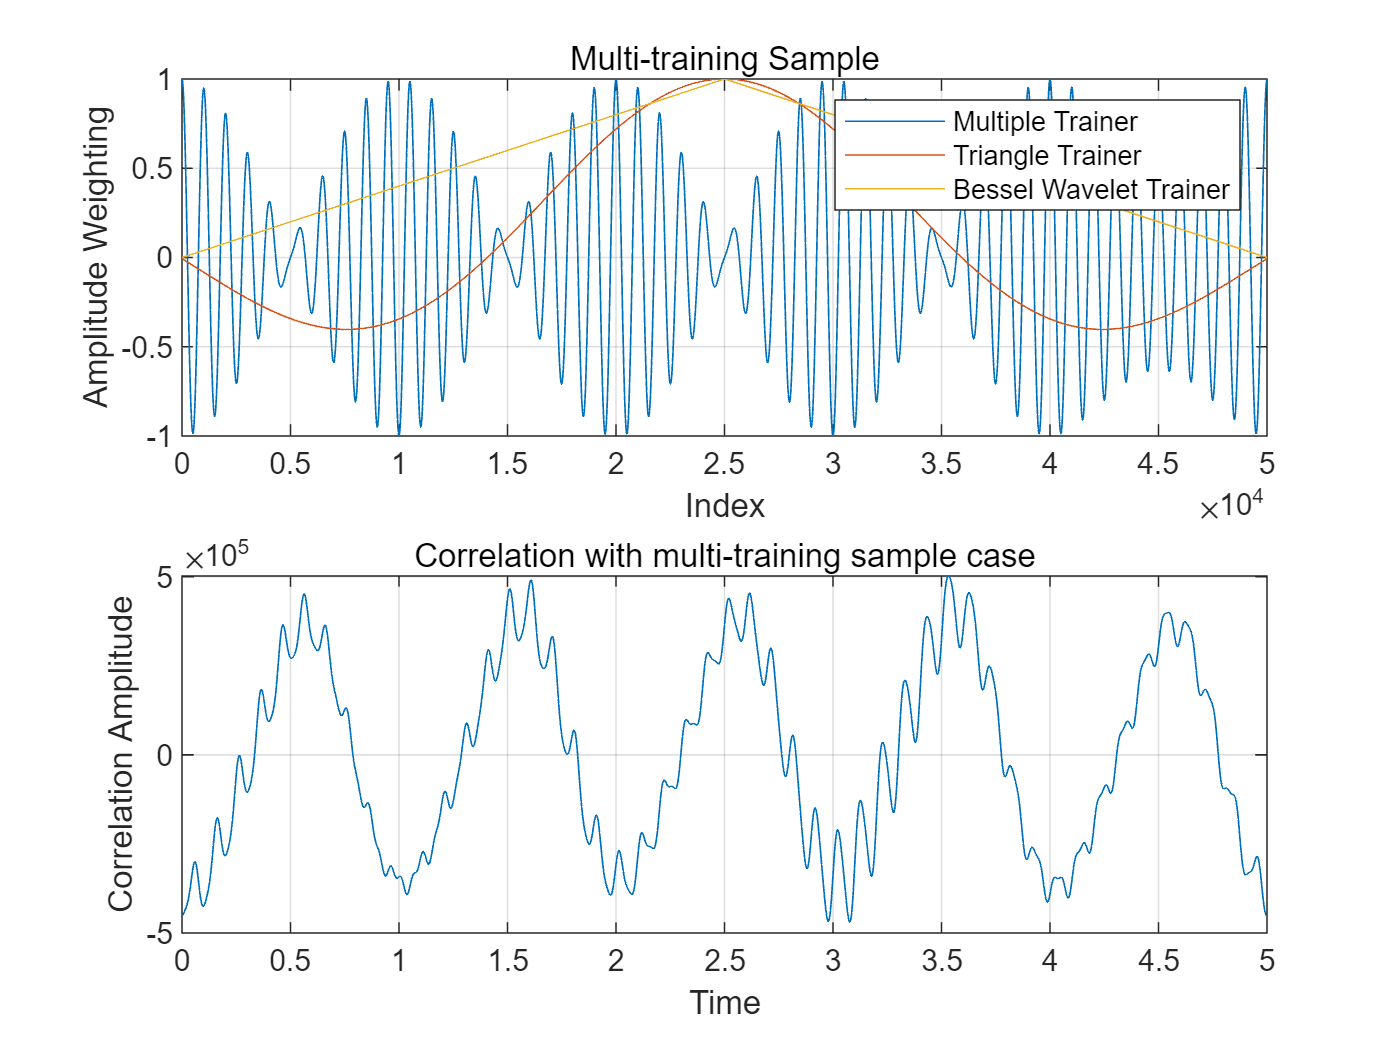

% --Define multiple training sets example
    g_hat_combo = g_hat_bessel .* g_hat_corr;
    g_combo = ifft(g_hat_combo);
    g_combo = g_combo ./ max(g_combo);

% --Output multiple training sets
    figure()
    subplot(2,1,1)
    plot(g_combo)
        hold on
        grid on
    plot(g_bessel)
    plot(g_triangle)
    xlabel('Index')
    ylabel('Amplitude Weighting')
    subtitle("Multi-training Sample")
    legend("Multiple Trainer", "Triangle Trainer", "Bessel Wavelet Trainer")
    xlim([0 50001])

% --Plotting the Correlation
    Rxyk_combo = ifft(kxxf .* conj((g_hat_combo .* (kyyf ))));


% --Plotting output
    subplot(2,1,2)
    plot(t1, Rxyk_combo)
    hold on
    grid on
    xlabel('Time')
    ylabel('Correlation Amplitude')
    subtitle('Correlation with multi-training sample case')

In the image above, we have succesffuly smoothed out the correlation ouput from the untrained samples and also kept some of the variation within the signal. The broad peak placement remains the same. 

The idea of multi-training projection samples within $\hat{g}$ should be finely tuned if not using a multi kernel case. For best performance, a multi-kernel dataset will have $p$ kernel transforms and $p$ training projections. Lets look at the math:

$\hat{G}_p \odot \hat{K}_p(y)$ where $\hat{G}_p = [\hat{g}_1, \hat{g}_2, ... \hat{g}_p]$ and $\hat{K}_p(y) = [\hat{k}_1(y), \hat{k}_2(y), ... \hat{k}_p(y)]$

therefore $\hat{G}_p$ will be of size [$n$ x $p$] given the signal has $n$ datapoints and there are $p$ kernels

The two can be multiplied element wise to create a correlator value for $\hat{H}^*$ that will be of size [$n$ x $p$] because we must do the same for the $\hat{K}_p(x)$ our output will then be a size [$n$ x $p$] and the overlapping correlations can be analyzed further. If $p$ outputs are desired, then it can be left, otherwise, multiplication in the frequency domain can convolve the outputs into a single output generating a relative weighting between each of the $p$ correlations yielding a single correlation output that is a linear combination of the $p$ kernels. 

## Multiple Reference Signals

Given there are multiple different reference signals we are able to check simultaneously as well, by constructing the vectors to be [$n$ x $m$] given the use of $m$ reference signals. For a single reference signal case $m =1$ then we will have the same kernel math as above. Multiple reference signals will have a $\hat{K}_t(x,x)$ of size [$n$ x $m$] where it repeats $m$ times. There can also be a variation where the number of different kernels used is $m$ or in other words $m = p$. The correlator will then be size [$n$ x $m$] as well and there will be $m$ different outputs that cannot be combined. 

Training still holds the same objective and sizes still need to match.

## Other Correlations

Given an image that is not [nx1] the correlation algorithm still holds provided the correct FFT calculations are done and the proper correlation training is done for an image case. This would require a [$n$ x $n$] sized training matrix for our mapping output. Otherwise, the correlation should remain the same. There are other connections to the calculations such as the rotation kernel correlation which can be used to correlate signals when camera rotation causes noise.

There is also a scale space filtering version which can be used as a scaled correlation by zero-padding the data signal with zeros of length $n$ which can be used for short time signals and enhanced signal detection for our signals. The signal will then be of size 2$n$. 

### Scale Kernel Filter

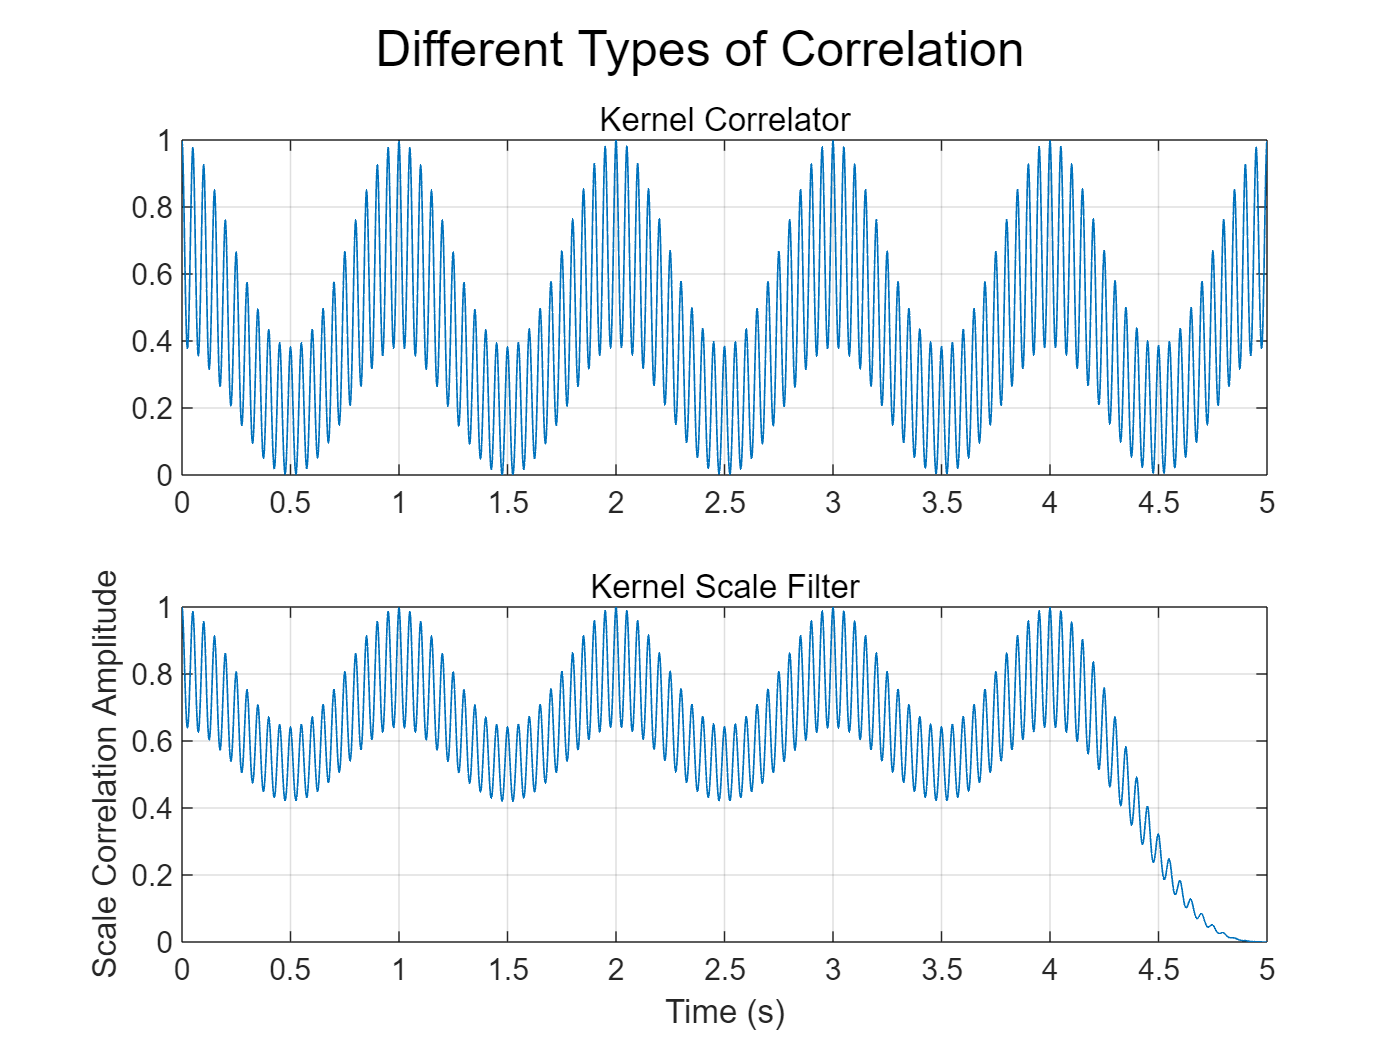

% --Setting up and finding kernels
    Kxx = Labs_kernel(signal, signal);
    append = zeros(1, length(Kxx));
    Kxx = [Kxx, append];
    
    Kyy = Labs_kernel(ref_signal_long, ref_signal_long);
    Kyy = [Kyy, append];

    Kxxf = fft(Kxx);
    Kyyf = fft(Kyy);

% --Finding correlation
    Rxy = ifft(Kxxf .* conj(Kyyf));
    Rxy = Rxy - min(Rxy);
    Rxy = Rxy ./ max(Rxy);
    Rxy = Rxy(1, 1:length(ref_signal_long));

% --Plot
    figure()
    subplot(2,1,2)
    plot(t1, Rxy)
        xlim([0 5])
        grid on
        hold on
        xlabel("Time (s)")
        ylabel("Scale Correlation Amplitude")
        sgtitle("Different Types of Correlation")
        subtitle("Kernel Scale Filter")

    subplot(2,1,1)
    plot(t1, Rxyk)
        hold on
        grid on
        subtitle("Kernel Correlator")

## Function Definitions

###    Linear Kernel

function kf = Labs_kernel(x, y) % Time domain defintion of kernel

    % --Find the kernel
        kf = abs(x + y);

end